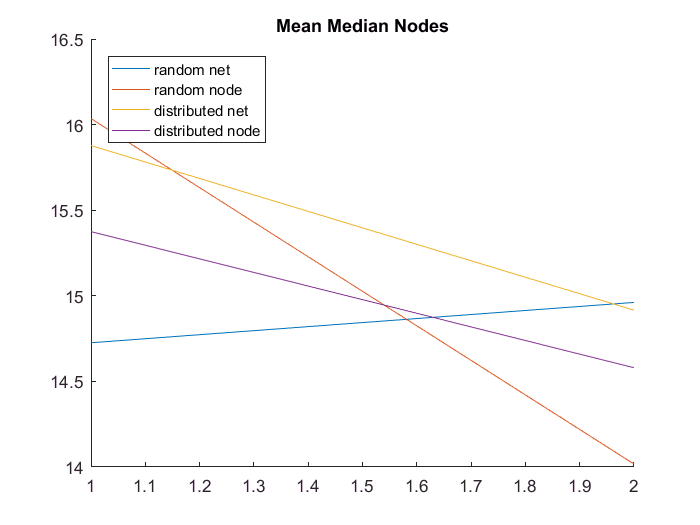

clear;
addpath('simulator');
p(1).topology = [6 2 1];
evaluationFunction = 'twoPoleEvaluation';
p(1).permutationOption = 1;
p(1).elitismOption = 1;
p(1).targetFitness = 1000;
p(1).maximumGenerations = 200;

p(2) = p(1);
p(2).permutationOption = 1;
p(2).elitismOption = 2;

p(3) = p(1);
p(3).permutationOption = 2;
p(3).elitismOption = 1;

p(4) = p(1);
p(4).permutationOption = 2;
p(4).elitismOption = 2;

nRuns = 30;

for experiment=1:4
  clearvars medianNodes bestNet medianNet r;
  medianNodes = ones(nRuns,p(experiment).maximumGenerations) * p(experiment).targetFitness; 
  bestNet = ones(nRuns,p(experiment).maximumGenerations) * p(experiment).targetFitness;
  medianNet = ones(nRuns,p(experiment).maximumGenerations) * p(experiment).targetFitness;
  for run=1:nRuns
    r(run) = doEsp(evaluationFunction, p(experiment));
    medianNodes(run,1:size(r(run).medianNodeFitness,2)) = mean(r(run).medianNodeFitness,1);
    bestNet(run,1:size(r(run).bestNetFitness,2)) = r(run).bestNetFitness;
    medianNet(run,1:size(r(run).medianNetFitness,2)) = r(run).medianNetFitness;

  end
  meanMedianNodes(experiment,:) = mean(medianNodes,1);
  meanBestNet(experiment,:) = mean(bestNet,1);
  meanMedianNet(experiment,:) = mean(medianNet,1);
end

figure(1); clf; hold on;
for i=1:4  
  plot(meanMedianNodes(i,:));
end
legend('random net','random node',...
  'distributed net','distributed node',...
  'Location','northwest');
title('Mean Median Nodes');

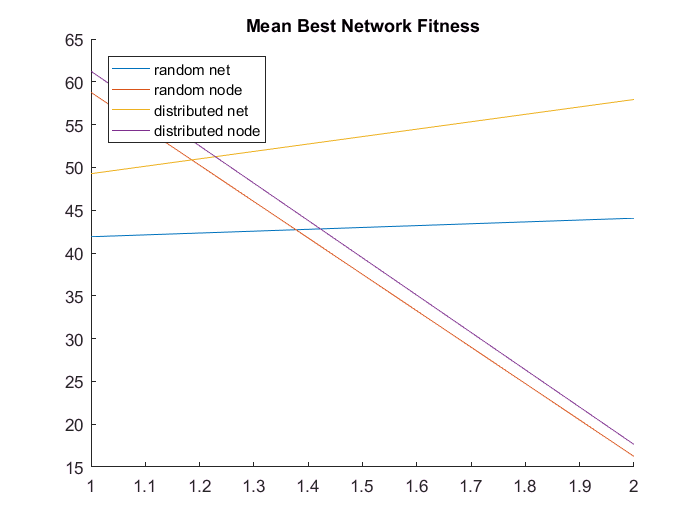


figure(2); clf; hold on;
for i=1:4  
  plot(meanBestNet(i,:));
end
legend('random net','random node',...
  'distributed net','distributed node',...
  'Location','northwest');
title('Mean Best Network Fitness');

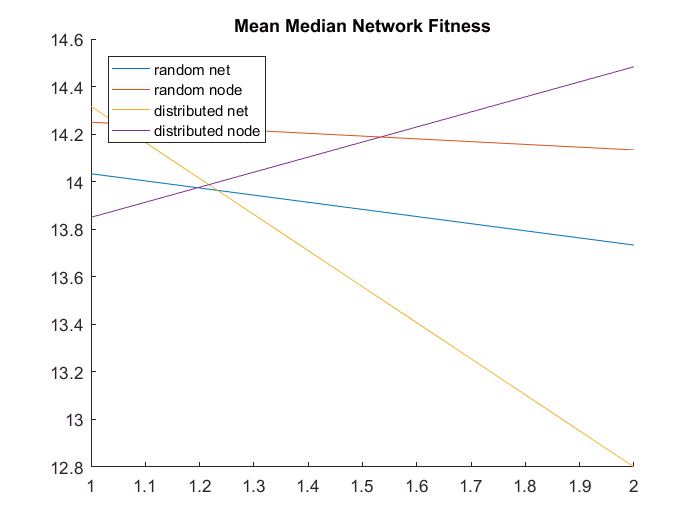


figure(3); clf; hold on;
for i=1:4  
  plot(meanMedianNet(i,:));
end
legend('random net','random node',...
  'distributed net','distributed node',...
  'Location','northwest');
title('Mean Median Network Fitness');